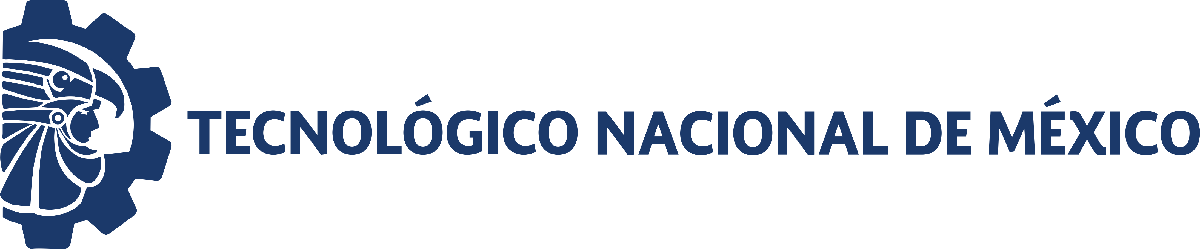                                 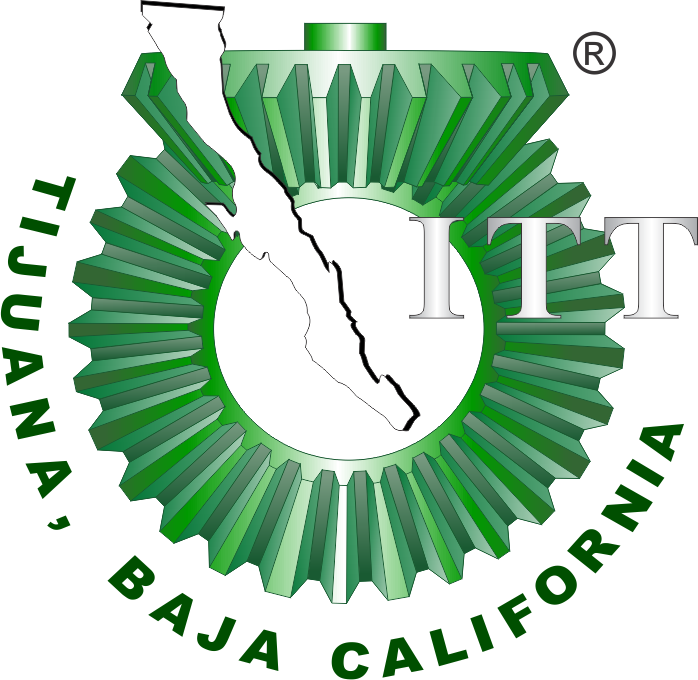

# Práctica cuatro: Sistema endócrino

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

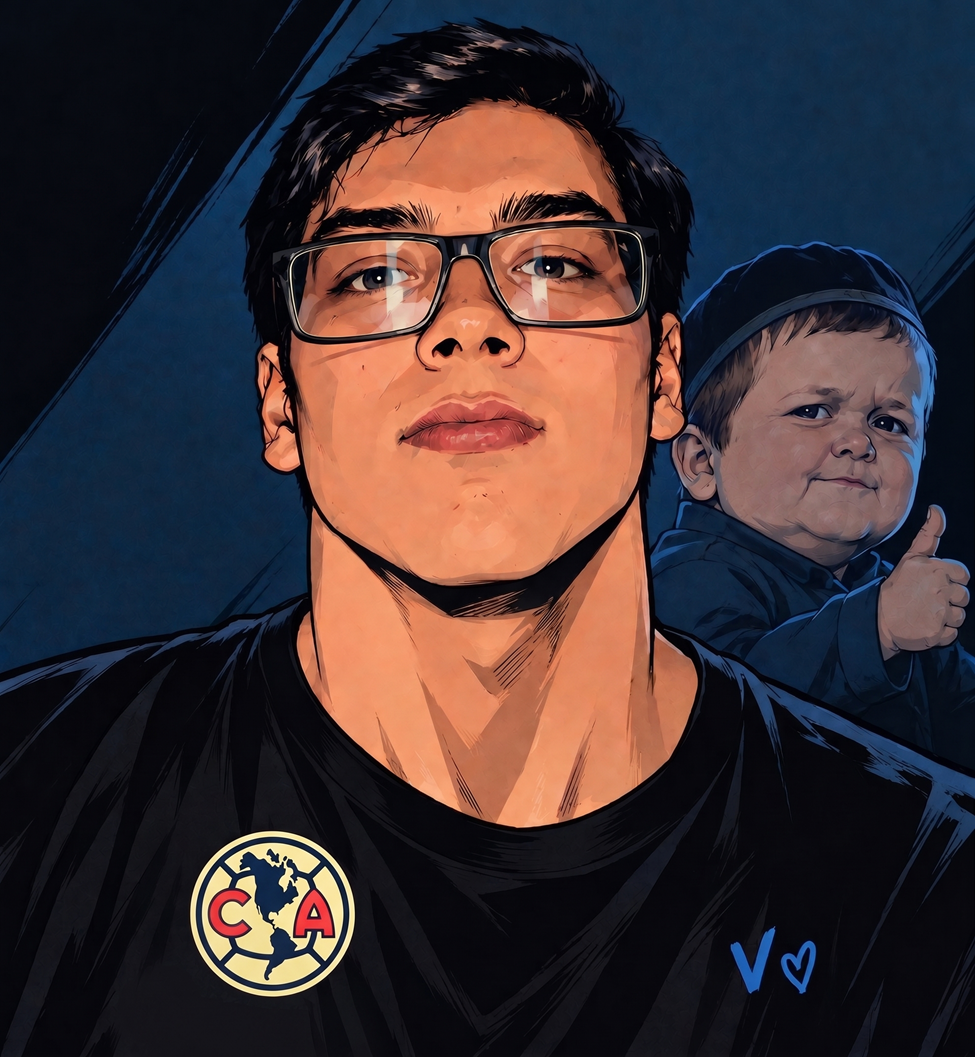

Nombre del alumno: Gabriel Fernando Trejo Paz

Número de control: 23212239

Correo institucional: **L23212239@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('sistema')
parameters.StopTime = '10';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-3';
X = sim('sistema',parameters);

## Respuesta al escalón 

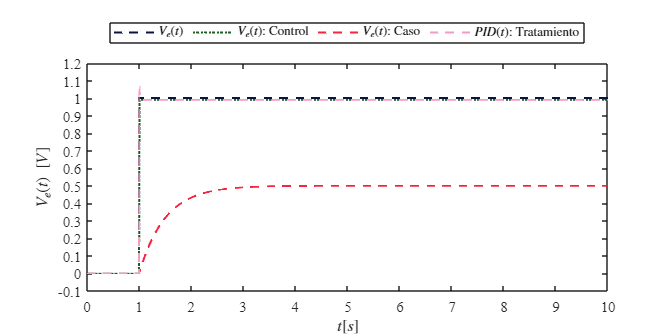

plotsignals(X.t,X.Ve,X.Vex,X.Vey,X.PID, 'Respuesta')

## Funcion: Respuestas de la simulacion

function plotsignals (t, Ve, Vex, VEy, PID, signal)
    set(figure(),'color','w')
    set(gcf,'units','inches','position',[1,1,7,3.5])
    set(gca,'fontname','times new roman','fontsize',11)
    hold on; grid off; box on;
    clr1 = [9,21,64]/255;   
    clr2 = [27,94,32]/255;
    clr3 = [246,36,64]/255;
    clr4 = [245, 153, 198]/255;
    order = [clr1;clr2;clr3;clr4]; colororder(order)

        plot(t, Ve, '--', t, Vex, ':', t, VEy, '--',...
             t, PID, '--','LineWidth', 1.5, 'MarkerSize', 5, 'MarkerIndices', 1:1e2:length(t));
        L = legend('$V_{e}(t)$', '$V_{e}(t)$: Control', '$V_{e}(t)$: Caso', '$PID(t)$: Tratamiento');
        

    set(L,'interpreter','latex','location','northoutside','orientation','horizontal')
    xlabel('$t[s]$','interpreter','latex')
    ylabel('$V_e(t)\ [V]$','interpreter','latex')

    xlim([0 10]); xticks(0:1:10)
    ylim([-0.1 1.2]); yticks(-0.1:0.1:1.2)
    

    exportgraphics(gcf,[signal, '_matlab.pdf'],'contenttype','vector')
end
